# DC Motor Speed: System Analysis

Key MATLAB commands used in this tutorial are: [`tf`](http://www.mathworks.com/help/toolbox/control/ref/tf.html) ,  [`step`](http://www.mathworks.com/help/toolbox/control/ref/step.html) , [`lsim`](https://www.mathworks.com/help/control/ref/lsim.html)

The details of a DC motor model are introduced in [DC Motor Speed: System Modeling](https://ctms.engin.umich.edu/CTMS/index.php?example=MotorSpeed&section=SystemModeling). Please refer to that page for the original problem setup and the derivation of the DC motor's governing equations. The open-loop transfer function model of the DC Motor is repeated below.


$$  P(s) = \frac{\dot{\Theta}(s)}{V(s)} = \frac{K}{(Js + b)(Ls + R) + K^2}  \qquad  [ \frac{rad/sec}{V} ] $$


The original parameters used in this example are as follows: 

For a 1-rad/sec step reference, the design criteria are the following.

- Settling time less than 2 seconds

- Overshoot less than 5%

- Steady-state error less than 1%

## Open-loop response

The following commands define the model for the motor and generate the open-loop speed response of the motor for a 1-Volt step input. 

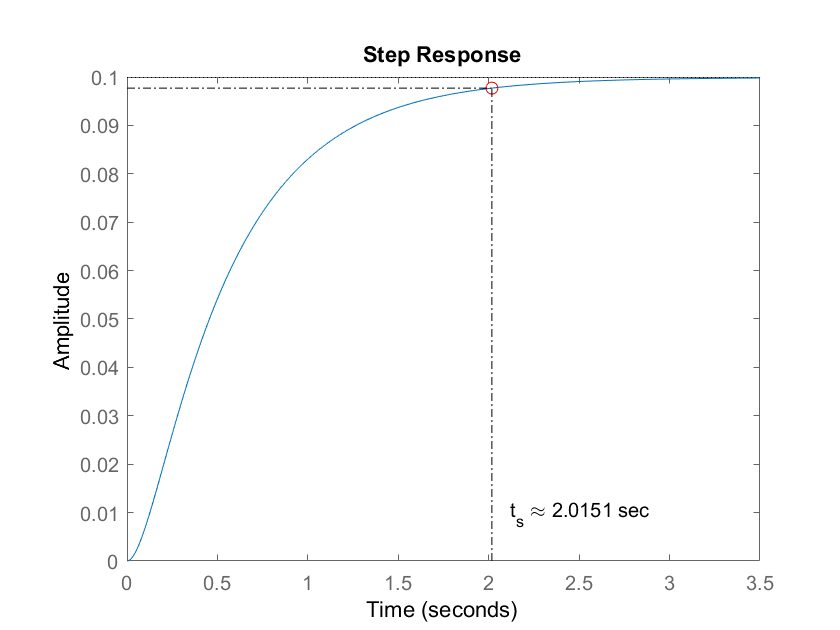

J = 0.01;
b = 0.1;
K = 0.01;
R = 1;
L = 0.5;
s = tf('s');
P_motor = K/((J*s+b)*(L*s+R)+K^2);
figure(1);
step(P_motor)
displaySettleTime(P_motor,0.02)

From the plot we see that when 1 Volt is applied to the system the motor can only achieve a maximum speed of 0.1 rad/sec, ten times smaller than our desired speed. Also, it takes the motor more than 2 seconds to reach its steady-state speed; this doesn't quite satisfy our settling time criterion. 

## Model Order Reduction

Since our open-loop transfer function has the form of a canonical second-order system, we should be able to accurately predict the step response characteristics observed above based on the transfer function's pole locations. The commands shown below generate the following map where the blue `x`'s identify the locations of poles. 

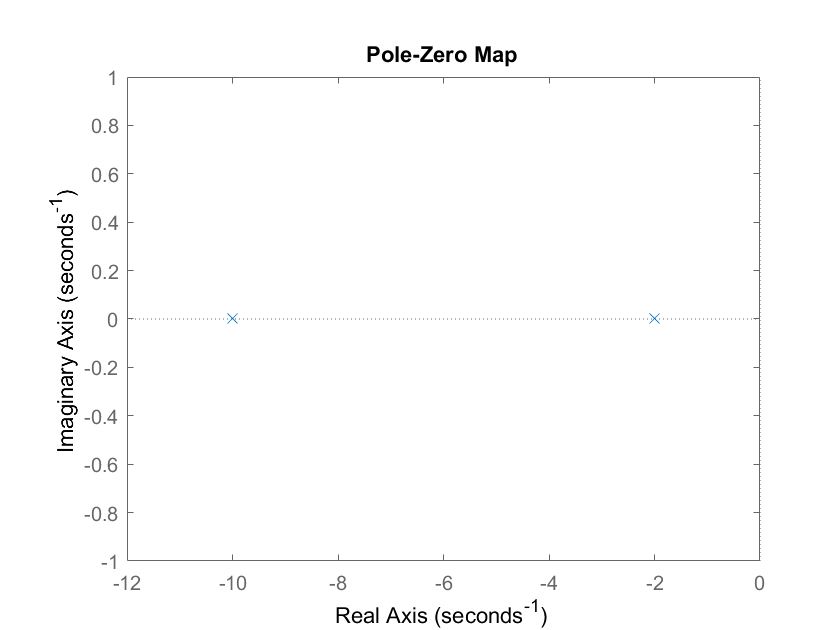

figure(2);
pzmap(P_motor);
axis([-12 0 -1 1])

From the figure you can see that the open-loop transfer function has two real poles, one at approximately *s* = -2 and one at approximately *s* = -10. Since both poles are real, there is no oscillation in the step response (or overshoot) as we have already seen. Furthermore, since the one pole is nearly 5 times more negative than the other, the slower of the two poles will dominate the dynamics. That is, the pole near *s* = -2 primarily determines the response speed of the system and the system behaves similarly to a first-order system. 

Let's see just how closely a first-order model approximates our original motor model. The code below builds a first-order transfer function with pole at *s* = -2 and steady-state gain matching the original transfer function, as well as comparing the step responses of the two models.

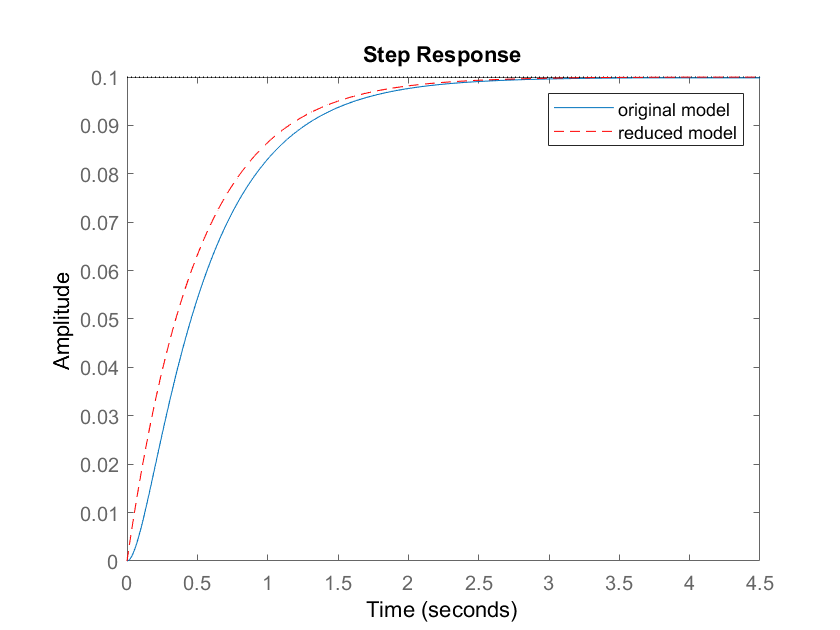

P_reduced = 0.1/(0.5*s+1);
figure(3);
step(P_motor);
hold on;
step(P_reduced,'r--')
legend('original model','reduced model')
hold off;

From the figure, we can see that a first-order approximation of our motor system is relatively accurate. The primary difference can be seen at t = 0 where a second-order system will have a derivative of zero, but our first-order model will not. 

With a first-order system, the settling time is equal to 


$$ T_s = 4 \tau $$


where $\tau$ is the time constant which in this case is 0.5. Therefore, our first-order model has a settling time of 2 seconds which is quite close to the settling time of our actual system. 

Let us now explore how well a reduced-order model approximates motors that have different characteristics. In the following, the slider allows us to generate models of motors with different motor torque constants $K$. Physically, one can consider that increasing the motor torque constant increases the "stiffness" of the motor. The same voltage input will generate more torque and faster speed response as $K$ is increased. Mathematically, recall the denominator of the motor's transfer function and how the poles of the model relate to the motor's parameters:


$$\begin{array}{l}
\left(\textrm{Js}+b\right)\left(\textrm{Ls}+R\right)+K^2 =\textrm{JL}s^2 +\left(\textrm{JR}+\textrm{bL}\right)s+\left(\textrm{bR}+K^2 \right)=0\\
\Rightarrow s=\frac{-\left(\textrm{JR}+\textrm{bL}\right)\pm \sqrt{{\left(\textrm{JR}+\textrm{bL}\right)}^2 -4\left(\textrm{JL}\right)\left(\textrm{bR}+K^2 \right)}}{2\left(\textrm{JL}\right)}
\end{array}$$
  

By inspection of the above, if we assume that motor model has real poles, the determinant (quantity under the square root) will be positive. Increasing the motor torque constant $K$ makes the determinant smaller, therefore, the two real poles will become closer together as $K$ is increased.  

K =0.01;
P_motor2 = K/((J*s+b)*(L*s+R)+K^2);
p = pole(P_motor2);
disp(['The poles for this value of motor torque constant are ',num2str(p(1)),' and ',num2str(p(2)),'.']);

The poles for this value of motor torque constant are -9.9975 and -2.0025.


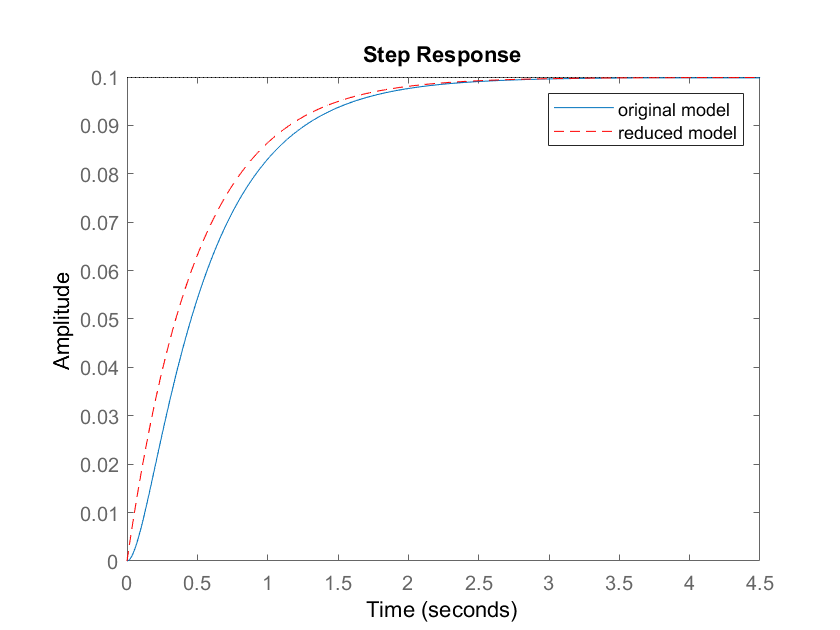

gain = K/(b*R+K^2);
tau = 1/(min(-p));
P_reduced2 = gain/(tau*s+1);
figure(4);
step(P_motor2);
hold on;
step(P_reduced2,'r--')
legend('original model','reduced model')
hold off;

As predicted, the two poles did become closer as $K$approached the value 0.28, with most of the change coming for values near 0.28. (For larger values of $K$, the poles become complex conjugates.) As the poles become closer, the difference in the "speed" of the modes associated with each pole becomes less different. Therefore, as demonstrated by the comparison of the step responses of the original and reduced models, it becomes less accurate to neglect the "fast" pole.

## Model Order Reduction with Live Tasks

We can also employ the **Reduced Order Model live editor task** to generate a lower order approximation of our motor model. This live editor task can employ a range of model order reduction techniques and allows you to specify the order of model you wish to generate as well as under which operating conditions you'd most like to preserve model performance. In the following, we specify that we will use the `Balanced Truncation` method to reduce our original second-order motor model to a first-order model. We also specify that we wish to match the DC gain of the reduced model to the original model.   

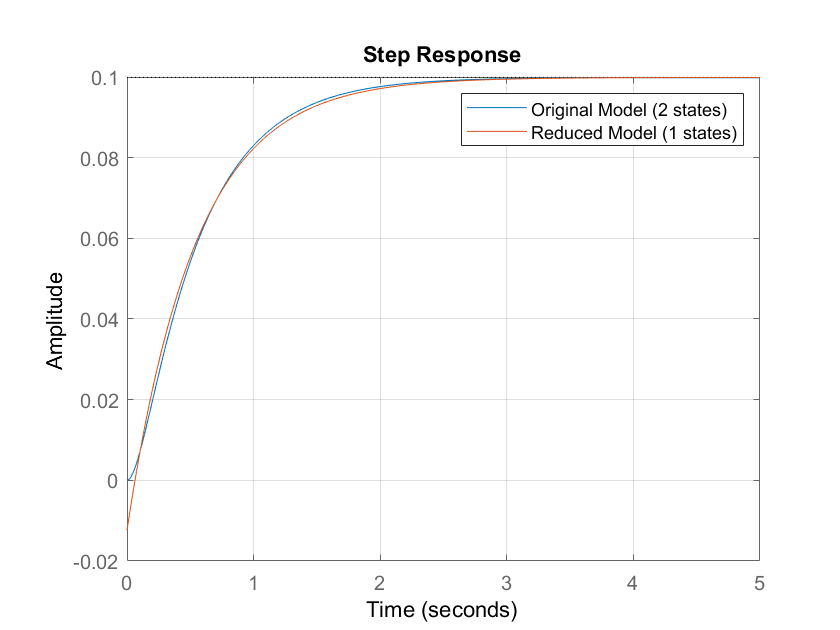

% Reduce LTI model order using balanced truncation
 
% Compute reduced order approximation
sysReduced = balred(P_motor,1);

% Compare original and reduced model
figure
stepplot(P_motor,sysReduced);
legend(['Original Model (',num2str(order(P_motor)),' states)'],...
       ['Reduced Model (',num2str(order(sysReduced)),' states)']);
grid on

Inspection of the above results show that the more advanced balanced truncation technique employed by the live editor task is able to achieve better agreement between the step response of the reduced-order model and the original system's step response. The following displays the reduced-order model that was generated revealing that this model includes a non-minimum phase zero in addition to a pole and DC gain similar to the reduced-order model we had generated previously. 

sysReduced

sysReduced =
 
  -0.01236 s + 0.185
  ------------------
      s + 1.852
 
Continuous-time transfer function.



Further inspection of the Bode plot generated by the live editor task shows that the reduced-order model is quite accurate for low frequency inputs, such as a step input, but that it doesn't agree with the true model very well for higher frequency inputs. Let's investigate the response of our models for different frequency sine inputs employing the `lsim` command. 

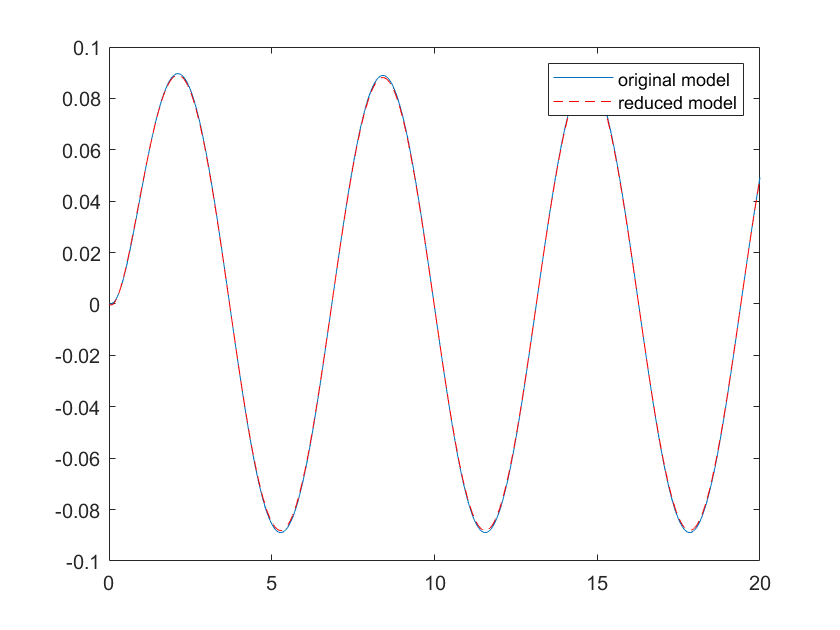

t = 0:0.01:20;  
w =1;
u = sin(w*t);   
y = lsim(P_motor,u,t);
yred = lsim(sysReduced,u,t);
plot(t,y,t,yred,'r--');
legend('original model','reduced model')

*The following function is used in the script above.*

function displaySettleTime(sys,threshold) 
[y,t] = step(sys);
stepResults = stepinfo(y,t,'SettlingTimeThreshold',threshold);
indexSettling = find(t>=stepResults.SettlingTime,1);
hold on;
plot(t(indexSettling),y(indexSettling),'ro');
plot([0 t(indexSettling)],[y(indexSettling) y(indexSettling)],'k-.');
plot([t(indexSettling) t(indexSettling)],[0 y(indexSettling)],'k-.');
text(stepResults.SettlingTime+0.1,0.01,['t_s \approx ',num2str(stepResults.SettlingTime),' sec']);
hold off;
end